## **UVP5-UVP6 intercalibration**

clear all
close all

disp('Version 2019/06/11')

Version 2019/06/11


## Analyse date

disp(['Processing date : ',datestr(now,31)])

Processing date : 2020-04-28 15:52:10


## Analyse operator

people = input('Enter people first and last name (default : Marc Picheral)','s');
if isempty(people); people = 'Marc Picheral'; end
disp(['Processing operator : ' char(people)]);

Processing operator : Marc Picheral


## Selection of REFERENCE instrument and data

ref_base_list = [];
ref_cast_list = [];
nb_of_ref = 0;
another_ref = 'y';
while another_ref == 'y'
    nb_of_ref = nb_of_ref +1;
    [ref_base, ref_cast] = CalibrationUvpOpenBase('Reference');
    [ref_base, ref_cast] = CalibrationUvpGetConfig(ref_base, ref_cast, 'Reference');
    ref_base_list = [ref_base_list, ref_base];
    ref_cast_list = [ref_cast_list, ref_cast];
    % ask for another reference
    disp('It is possible to add another reference cast')
    disp('The adjusted cast will be compared to the mean of the reference casts')
    disp('ATTENTION ! : only for uvp6')
    another_ref = input('Add another REFERENCE PROFILE ? ([n]/y) ','s');
    if isempty(another_ref);another_ref = 'n';end
end

>> Select UVP Reference project directory
----------- Base list --------------------------------
1 database in C:\uvp5_sn203_intercalibrage_20190207\results\
N°= 1 : baseuvp5_sn203_intercalibrage_20190207_cal.mat
------------------------------------------------------
Number : 1   >  Profile : cast_aa
Number : 2   >  Profile : cast_ab
Number : 3   >  Profile : cast_ac
Number : 4   >  Profile : cast_ad
Number : 5   >  Profile : cast_ae
Number : 6   >  Profile : cast_af
Number : 7   >  Profile : cast_ag
Number : 8   >  Profile : cast_ah
Number : 9   >  Profile : cast_ai
Number : 10   >  Profile : cast_aj


All metadata of the reference profile are OK.


It is possible to add another reference cast


The adjusted cast will be compared to the mean of the reference casts


ATTENTION ! : only for uvp6


## Selection of instrument and data to adjust

[adj_base, adj_cast] = CalibrationUvpOpenBase('Adjusted');

>> Select UVP Adjusted project directory
----------- Base list --------------------------------
1 database in C:\uvp6_sn000004lp_20190207_intercalibrage\results\
N°= 1 : baseuvp6_sn000004lp_20190207_intercalibrage.mat
------------------------------------------------------
Number : 1   >  Profile : 20190207-122915_sample_1
Number : 2   >  Profile : 20190207-124845_sample_2
Number : 3   >  Profile : 20190207-130107_sample_3
Number : 4   >  Profile : 20190207-131211_sample_4
Number : 5   >  Profile : 20190207-132304_sample_5
Number : 6   >  Profile : 20190207-133442_sample_6
Number : 7   >  Profile : 20190207-134610_sample_7
Number : 8   >  Profile : 20190207-135724_sample_8
Number : 9   >  Profile : 20190207-140829_sample_9
Number : 10   >  Profile : 20190207-141915_sample_10


[adj_base, adj_cast] = CalibrationUvpGetConfig(adj_base, adj_cast, 'Adjusted');

%% Calibration parameters
process_params = CalibrationUvpGetUserProcessParams(adj_cast.uvp, adj_cast.pix);

## Raw data visualization

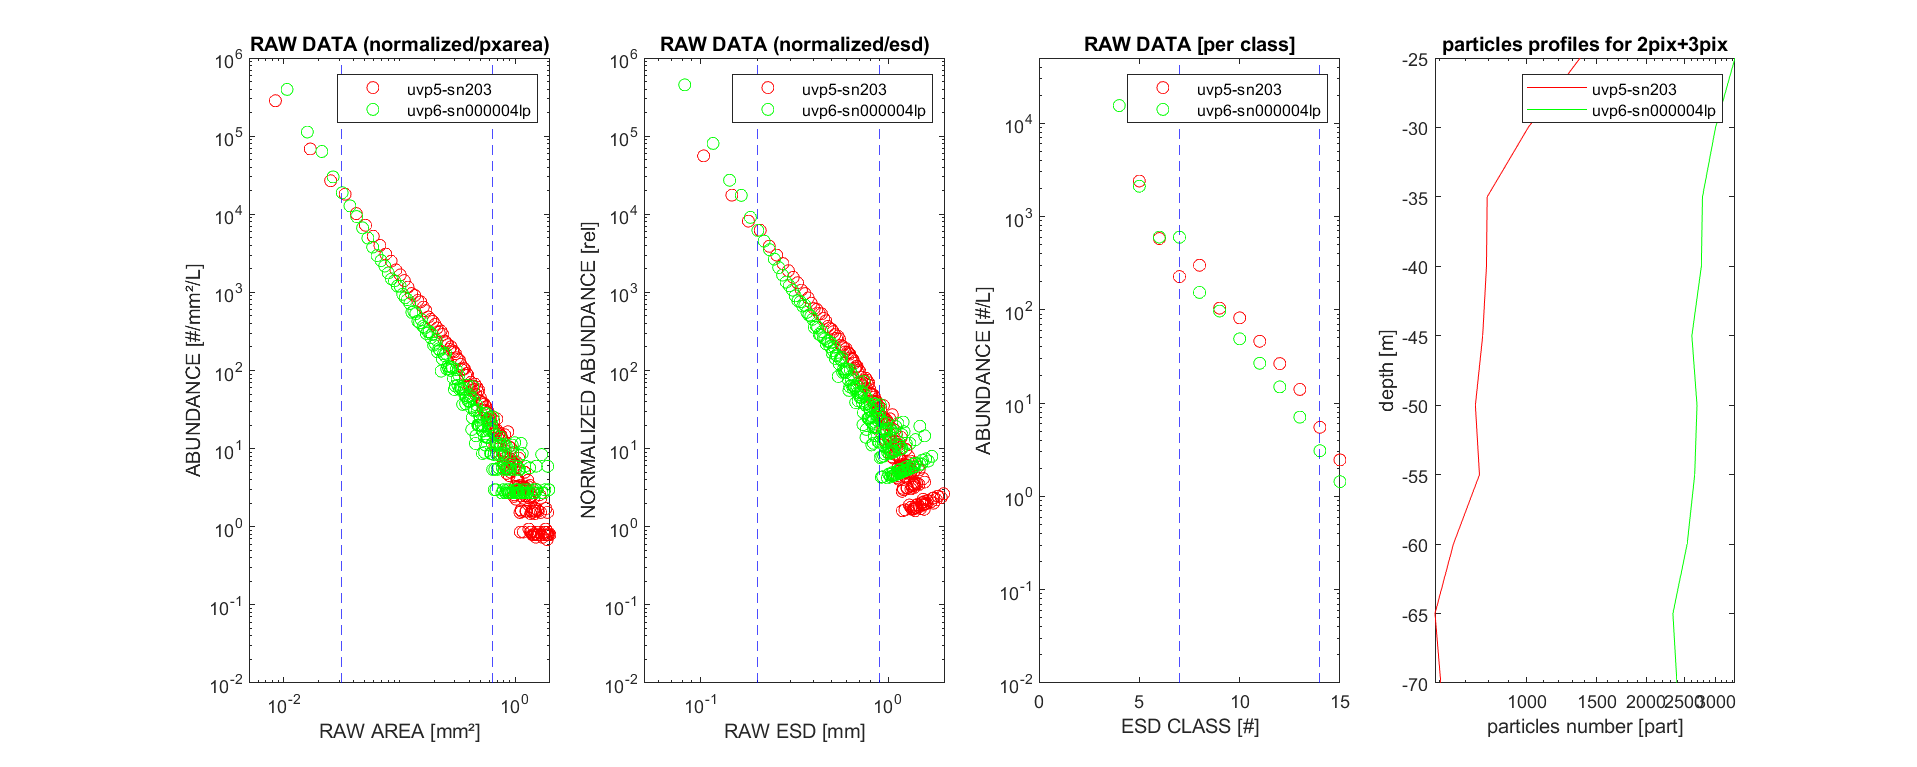

%mean raw data for ref and common depth
if length(ref_cast_list)>1
    multiple_ref = 1;
else
    multiple_ref = 0;
end
if multiple_ref
    for i = 2:length(ref_base_list)
        [ref_base_list(1).histopx, ref_base_list(i).histopx, ~] = CalibrationUvpComputeDepthRange(ref_base_list(1).histopx, ref_base_list(i).histopx);
    end
    ref_base = Uvp6MeanInstruRawBases(ref_base_list);
    ref_cast = ref_cast_list(1);
    ref_cast.img_vol_data = ref_base.volimg0;
    ref_cast.pix = ref_base.pixel_size;
    ref_cast.uvp = 'mean';
end

% check and select the same depth range
[ref_cast.histopx, adj_cast.histopx, process_params.depth] = CalibrationUvpComputeDepthRange(ref_base.histopx,adj_base.histopx);

% process raw data variale for plot and fit
[ref_cast] = CalibrationUvpProcessRawData(process_params.esd_vect_ecotaxa, ref_cast);
[adj_cast] = CalibrationUvpProcessRawData(process_params.esd_vect_ecotaxa, adj_cast);

% plot
CalibrationUvpPlotRawData(process_params, ref_cast, adj_cast);

% cut variables from size range
ref_cast = CalibrationUvpAdaptToSizeRange(ref_cast, process_params.esd_min, process_params.esd_max);
adj_cast_uncut = adj_cast;
adj_cast = CalibrationUvpAdaptToSizeRange(adj_cast, process_params.esd_min, process_params.esd_max);

%% Compute reference calib data
[ref_cast] = CalibrationUvpProcessCalibratedData(process_params.esd_vect_ecotaxa, ref_cast, ref_cast.aa_data, ref_cast.expo_data);
ref_esd_calib_log = ref_cast.esd_calib_log;
ref_histo_mm2_vol_mean = ref_cast.histo_mm2_vol_mean;
% for mean of multiple ref
if multiple_ref
    disp('Raw data visualisation for each reference');
    ref_esd_calib_log = [];
    ref_histo_mm2_vol_mean = [];
    ref_cast_list_old = ref_cast_list;
    ref_cast_list = [];
    for i = 1:length(ref_cast_list_old)
        ref_cast_new = ref_cast_list_old(i);
        [ref_cast_new.histopx, ~, ~] = CalibrationUvpComputeDepthRange(ref_base_list(i).histopx, adj_cast_uncut.histopx);
        [ref_cast_new] = CalibrationUvpProcessRawData(process_params.esd_vect_ecotaxa, ref_cast_new);
        CalibrationUvpPlotRawData(process_params, ref_cast_new, adj_cast_uncut);
        ref_cast_new = CalibrationUvpAdaptToSizeRange(ref_cast_new, process_params.esd_min, process_params.esd_max);
        ref_cast_new = CalibrationUvpProcessCalibratedData(process_params.esd_vect_ecotaxa, ref_cast_new, ref_cast_new.aa_data, ref_cast_new.expo_data);
        ref_esd_calib_log = [ref_esd_calib_log ref_cast_new.esd_calib_log];
        ref_histo_mm2_vol_mean = [ref_histo_mm2_vol_mean ref_cast_new.histo_mm2_vol_mean];
        ref_cast_list = [ref_cast_list, ref_cast_new];
    end
end

## Fitting on reference data

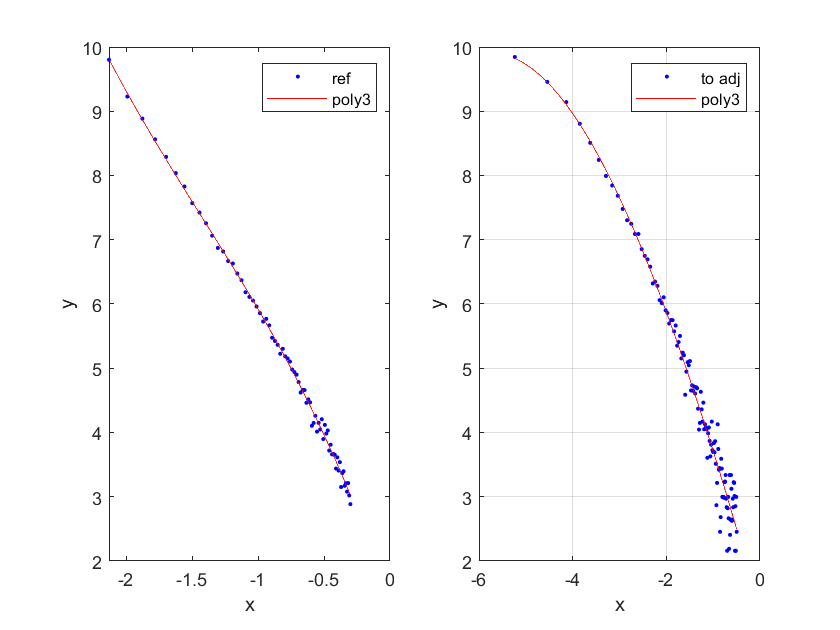

[fitresult] = create_two_fits(ref_esd_calib_log,log(ref_histo_mm2_vol_mean),process_params.fit_type,1,log([1:numel(adj_cast.histo_mm2_vol_mean)].*(adj_cast.pix^2)),log(adj_cast.histo_mm2_vol_mean),process_params.Fit_range);  

[datahistref] = poly_from_fit(ref_esd_calib_log,fitresult,process_params.fit_type);

## Processing calibration

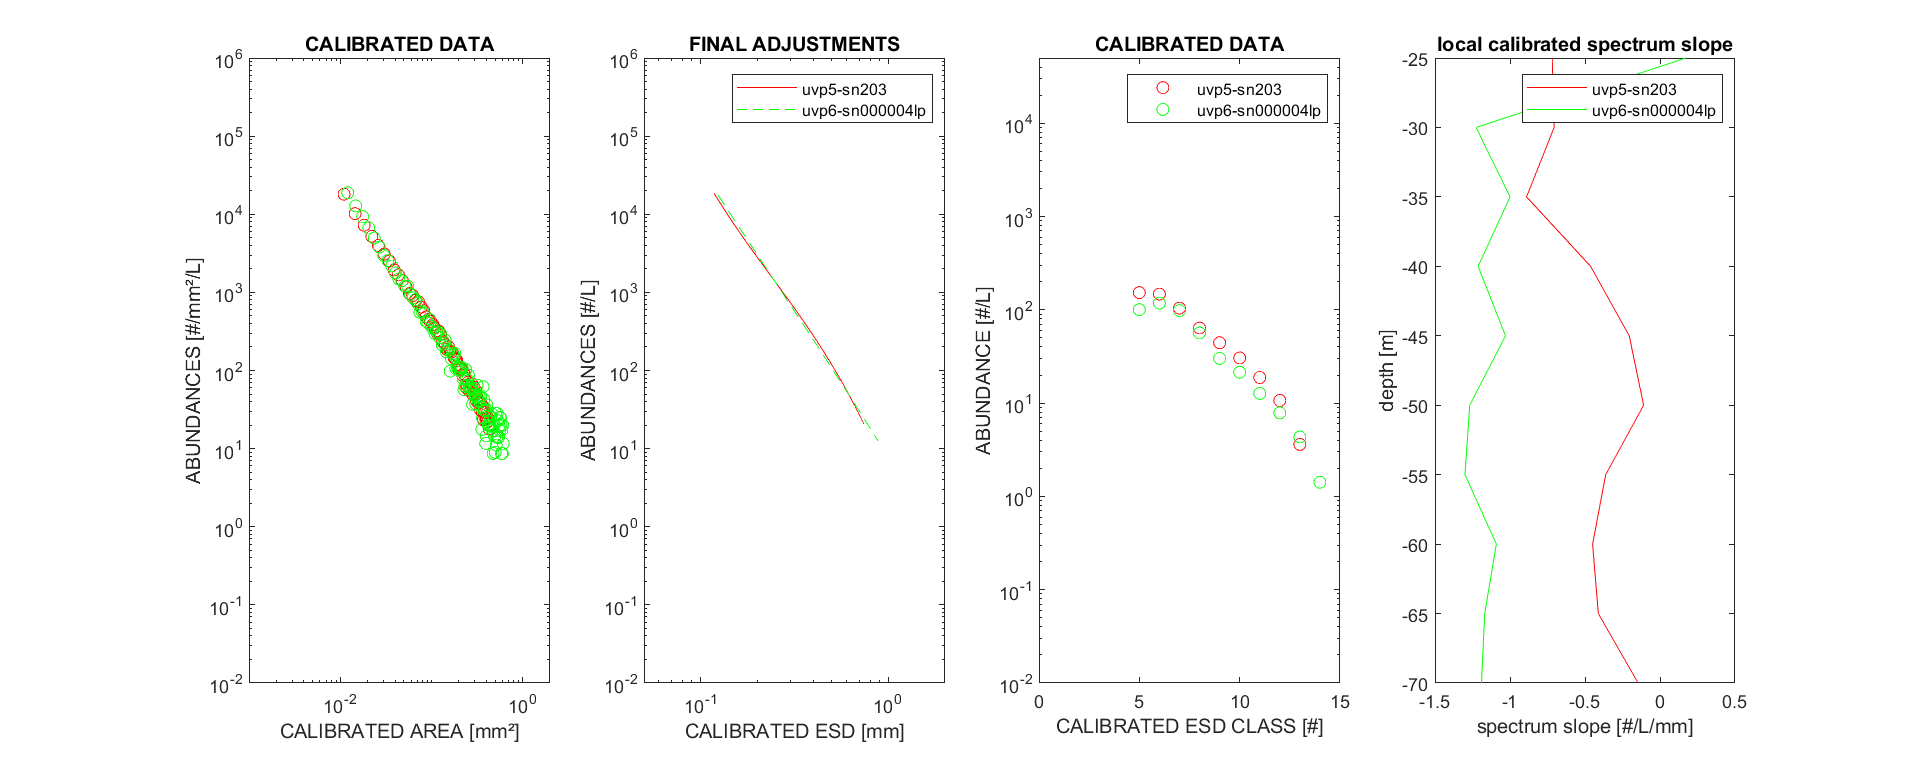

% optimisation of aa and exp for adj
objective_function = @(x)histofunction7_new(x,datahistref, adj_cast.pixsize, adj_cast.histo_mm2_vol_mean, ref_esd_calib_log, process_params.fit_type);
[X,feval]=fminsearch(objective_function,process_params.X0);
aa_adj = X(1);
expo_adj = X(2);

% process adj calibrated data
[adj_cast] = CalibrationUvpProcessCalibratedData(process_params.esd_vect_ecotaxa, adj_cast, aa_adj, expo_adj);


% ---------- fit on calibrated data ---------------------------------------
[fitresult] = create_two_fits(adj_cast.esd_calib_log,adj_cast.histo_mm2_vol_mean_log,process_params.fit_type,0,adj_cast.esd_calib_log,adj_cast.histo_mm2_vol_mean_log,process_params.fit_type);
[yresults_adj] = poly_from_fit(adj_cast.esd_calib_log,fitresult,process_params.fit_type);

%% RATIO
% -------------- Ratio ne fonctionne ici QUE si mêmes tailles pixels ------
if ref_cast.pix == adj_cast.pix
    [yresults_adj_ratio] = poly_from_fit(ref_esd_calib_log,fitresult,process_params.fit_type);
    ratio = yresults_adj_ratio./datahistref;
    process_params.ratio_mean = nanmean(ratio);
else
    process_params.ratio_mean = 1;
    ratio = 1;
end


%% SCORE
% -------------- Pour calcul Score final -----------------------------
[score_hist] = poly_from_fit(ref_esd_calib_log,fitresult,process_params.fit_type);
process_params.Score = data_similarity_score(exp(score_hist), exp(datahistref));

% plot
if multiple_ref
    for i = 1:length(ref_cast_list)
        CalibrationUvpPlotCalibratedData(process_params, ref_cast_list(i), adj_cast, datahistref, yresults_adj, ref_esd_calib_log)
    end
else
   CalibrationUvpPlotCalibratedData(process_params, ref_cast, adj_cast, datahistref, yresults_adj, ref_esd_calib_log) 
end

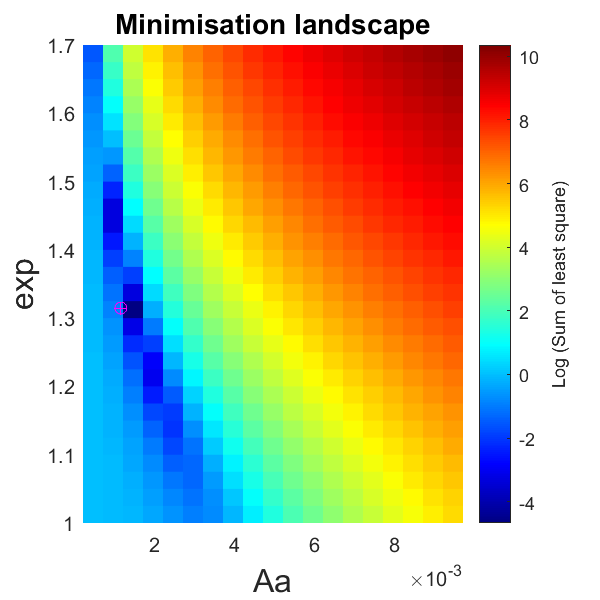

CalibrationUvpPlotMinimisationSpace(ref_cast, adj_cast, datahistref, aa_adj, expo_adj, process_params.fit_type, ref_esd_calib_log);

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

## Results

if multiple_ref
    CalibrationUvpPrintResults(process_params, ref_cast_list, adj_cast, aa_adj, expo_adj)
else
   CalibrationUvpPrintResults(process_params, [ref_cast], adj_cast, aa_adj, expo_adj) 
end

-------------------------------------------------------------------------
Processing date     : 2020-04-28 15:53:32
-------------------------------------------------------------------------
Nb of reference uvps: 1
Min ESD       [mm]  : 0.2
Max ESD       [mm]  : 0.9
Mnimisation start   : [0.0029309 1.1]
Fit                 : poly3
EC factor           : 0.5
EC                  : 0.0086398
Ratio (after adjust): 1
-------------------------------------------------------------------------
Reference UVP       : uvp5-sn203
Light 1             :  h001
Light 2             :  h008
Reference folder    : uvp5_sn203_intercalibrage_20190207
Reference profile   : 20190207124035
Reference profile # : 1
Observed volume [L] : 148.35
Shutter             : 9999
Gain                : 200
Threshold           : 3
Exposure            : 135
SMBase              : 1
Image volume [L]    : 1.15
Pixel        [µm]   : 0.092
Pixel Area   [µm²]  : 0.008464
Aa                  : 0.00195
Exp                 : 1.25
------